ButterFlyVideo = VideoReader("butterfly.mp4")

ButterFlyVideo =   VideoReader with properties:

   General Properties:
            Name: 'butterfly.mp4'
            Path: 'C:\Users\21692\Desktop\Etudes en France\IMT\FISEA2\Computer Vision\Project\Butterfly'
        Duration: 8.3833
     CurrentTime: 0
       NumFrames: 251

   Video Properties:
           Width: 416
          Height: 320
       FrameRate: 30
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


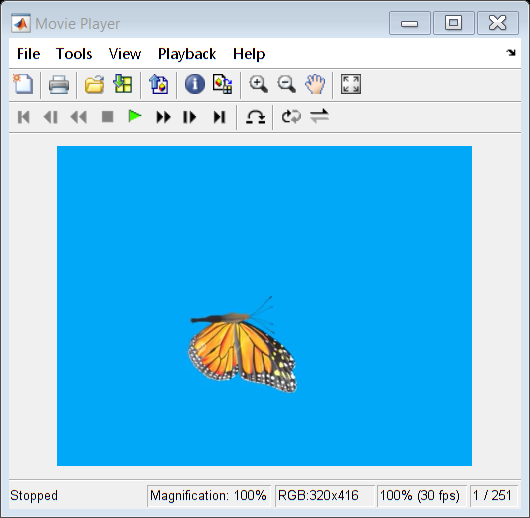

implay("butterfly.mp4")

firest_frame = read(ButterFlyVideo,1);
[BW,maskedRGBImage] = createMaskButterfly(firest_frame);

numFrames_butterfly= ButterFlyVideo.NumFrames;
v_seg= VideoWriter("Boxed_Butterfly","MPEG-4");

v_seg.FrameRate = ButterFlyVideo.FrameRate;
v_seg_comb.FrameRate = ButterFlyVideo.FrameRate;
%open(v_seg);
bboxes = [];
idxes = [];
for i = 1 : numFrames_butterfly
    frame = read(ButterFlyVideo,i);
    idx = string(i);
    while strlength(idx) ~= 3
        idx = append("0",idx);
    end
    %imwrite(frame,"Butterfly-"+idx+".png");
    [Th,maskedRGBImage] = createMaskButterfly(frame);
    [BW,maskedImage] = segmentImageThresholded(maskedRGBImage);
    BW = filterRegionsButterfly(BW);
    imwrite(BW,"MaskedButterfly-"+idx+".bmp");
    props = regionprops("table",BW,"BoundingBox");
    BoxedButterfly =insertShape(frame,"Rectangle",props.BoundingBox,"LineWidth",3,"Color","yellow");
    %writeVideo(v_seg, BoxedButterfly);
    bboxes = [bboxes;props];
    idxes = [idxes;i];
end
%close(v_seg);

coords=[];
coords.frames= idxes;
coords.x1 = bboxes.BoundingBox(:,1);
coords.y1 = bboxes.BoundingBox(:,2);
coords.w = bboxes.BoundingBox(:,3);
coords.h = bboxes.BoundingBox(:,4);

coords = struct2table(coords);
writetable(coords,"coords.txt");

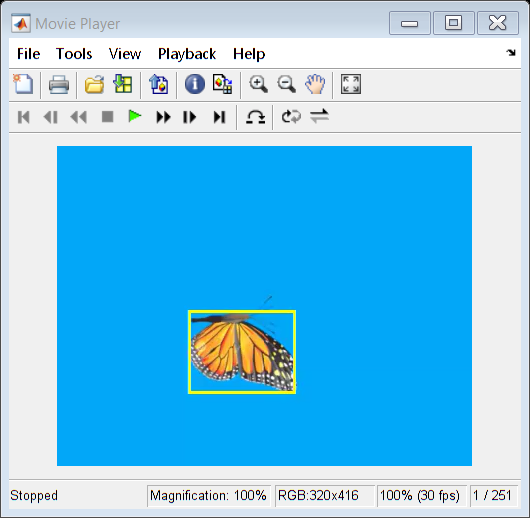

implay("Boxed_Butterfly.mp4")